# Red Neuronal Convolucional Siamesa

clc
clear all

## 1 Carga de datos

% Definición del path con los pares de plagio
dataFolderTrain = 'C:\2\TFG\TFG programa\pair'

dataFolderTrain = 'C:\2\TFG\TFG programa\pair'

% Carga de datos imagen
imds_total = imageDatastore(dataFolderTrain, ...
    IncludeSubfolders=true, ...
    LabelSource="none");

files = imds_total.Files(randperm(length(imds_total.Files)));
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),"-");
imds_total.Labels = categorical(labels);


% Verificación de input
% idx = randperm(numel(imdsTrain.Files),8);
%
% for i = 1:numel(idx)
%    subplot(4,2,i)
%    imshow(readimage(imdsTrain,idx(i)))
%    title(imdsTrain.Labels(idx(i)),Interpreter="none");
% end

% Comprobación del funcionamiento
% batchSize = 10;
% [pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize)
% for i = 1:batchSize
%    if pairLabel(i) == 1
%        s = "similar";
%    else
%        s = "dissimilar";
%    end
%    subplot(2,5,i)
%    imshow([pairImage1(:,:,:,i) pairImage2(:,:,:,i)]);
%    title(s)
% end

## 2 Arquitectura de la CNN

% Definición de las capas de la CNN:
layers = [
    imageInputLayer([262 350 3],Normalization="zscore",NormalizationDimension = "auto", Mean = 0, StandardDeviation = 1, Name = "Input")
    convolution2dLayer(10,64,WeightsInitializer="narrow-normal",BiasInitializer="narrow-normal", WeightLearnRateFactor = 1, BiasLearnRateFactor = 1)
    reluLayer
    maxPooling2dLayer(2,Stride=2)
    convolution2dLayer(7,128,WeightsInitializer="narrow-normal",BiasInitializer="narrow-normal")
    reluLayer
    maxPooling2dLayer(2,Stride=2)
    convolution2dLayer(4,256,WeightsInitializer="narrow-normal",BiasInitializer="narrow-normal")
    reluLayer
    maxPooling2dLayer(2,Stride=2)
    convolution2dLayer(5,512,WeightsInitializer="narrow-normal",BiasInitializer="narrow-normal")
    reluLayer
    fullyConnectedLayer(256,WeightsInitializer="narrow-normal",BiasInitializer="narrow-normal")
    %fullyConnectedLayer(1,WeightsInitializer="narrow-normal",BiasInitializer="narrow-normal")
    ]

layers =   13×1 Layer array with layers:

     1   'Input'   Image Input       262×350×3 images with 'zscore' normalization
     2   ''        2-D Convolution   64 10×10 convolutions with stride [1  1] and padding [0  0  0  0]
     3   ''        ReLU              ReLU
     4   ''        2-D Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     5   ''        2-D Convolution   128 7×7 convolutions with stride [1  1] and padding [0  0  0  0]
     6   ''        ReLU              ReLU
     7   ''        2-D Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]
     8   ''        2-D Convolution   256 4×4 convolutions with stride [1  1] and padding [0  0  0  0]
     9   ''        ReLU              ReLU
    10   ''        2-D Max Pooling   2×2 max pooling with stride [2  2] and padding [0  0  0  0]
    11   ''        2-D Convolution   512 5×5 convolutions with stride [1  1


% Visualización de la CNN
lgraph = layerGraph(layers)

lgraph =   LayerGraph with properties:

     InputNames: {'Input'}
    OutputNames: {1×0 cell}
         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [12×2 table]


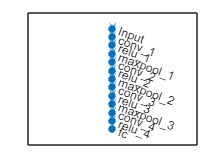

figure
plot(lgraph)


% Creación de la red CNN
net = dlnetwork(lgraph)

net =   dlnetwork with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [12×2 table]
     Learnables: [10×3 table]
          State: [0×3 table]
     InputNames: {'Input'}
    OutputNames: {'fc'}
    Initialized: 1

  View summary with summary.



% Definición de los pesos
fcWeights = dlarray(0.01*randn(1,256));
fcBias = dlarray(0.01*randn(1,1));
fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

## 3) Entrenamiento de la SCNN

% Definición del número de iteraciones, el tamaño de cada muestra y el
% porcentaje de dataset destinado al entrenamiento.
numIterations = 1000;

numIterations = 1000

miniBatchSize = 10;

miniBatchSize = 10

training_perc = 80;

num_training = roung(training_perc * numel(imds.Files /100));
imds_train = subset(imds_total, 1:num_training)
files_train = imds_train.Files;
parts_train = split(files_train,filesep);
labels_train = join(parts_train(:,(end-2):(end-1)),"-");
imds_train.Labels = categorical(labels_train);

% Especificación de los parámetros para la optimizacion ADAM:
learningRate = 6e-5;
gradDecay = 0.9;
gradDecaySq = 0.99;

% Definición del modo de ejecución (para GPU poner "auto" sino poner "cpu")
executionEnvironment = "auto";

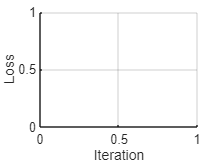

% Inicialización de la gráfica dinámica: Función de pérdida vs. Iteración
figure
C = colororder;
lineLossTrain = animatedline(Color=C(2,:));
ylim([0 inf])
xlabel("Iteration")
ylabel("Loss")
grid on

% Inicialización de los parámetros del solver
trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];

% Comprobación de los pares
%
% for i = 1:batchSize
%    if pairLabel(i) == 1
%        s = "similar";
%    else
%        s = "dissimilar";
%    end
%    subplot(2,5,i)
%    imshow([pairImage1(:,:,:,i) pairImage2(:,:,:,i)]);
%    title(s)
% endstart = tic;
% end 

start = tic;
disp('Iteration:')

Iteration:


     1



lossValue = 0.6921

     2



lossValue = 0.6965

     3



lossValue = 0.6937

     4



lossValue = 0.6932

     5



lossValue = 0.6931

     6



lossValue = 0.6931

     7



lossValue = 0.6927

     8



lossValue = 0.6930

     9



lossValue = 0.6930

    10



lossValue = 0.6928

    11



lossValue = 0.6928

    12



lossValue = 0.6933

    13



lossValue = 0.6928

    14



lossValue = 0.6931

    15



lossValue = 0.6933

    16



lossValue = 0.6933

    17



lossValue = 0.6933

    18



lossValue = 0.6933

    19



lossValue = 0.6935

    20



lossValue = 0.6928

    21



lossValue = 0.6937

    22



lossValue = 0.6933

    23



lossValue = 0.6931

    24



lossValue = 0.6931

    25



lossValue = 0.6931

    26



lossValue = 0.6935

    27



lossValue = 0.6931

    28



lossValue = 0.6930

    29



lossValue = 0.6931

    30



lossValue = 0.6930

    31



lossValue = 0.6933

    32



lossValue = 0.6933

    33



lossValue = 0.6933

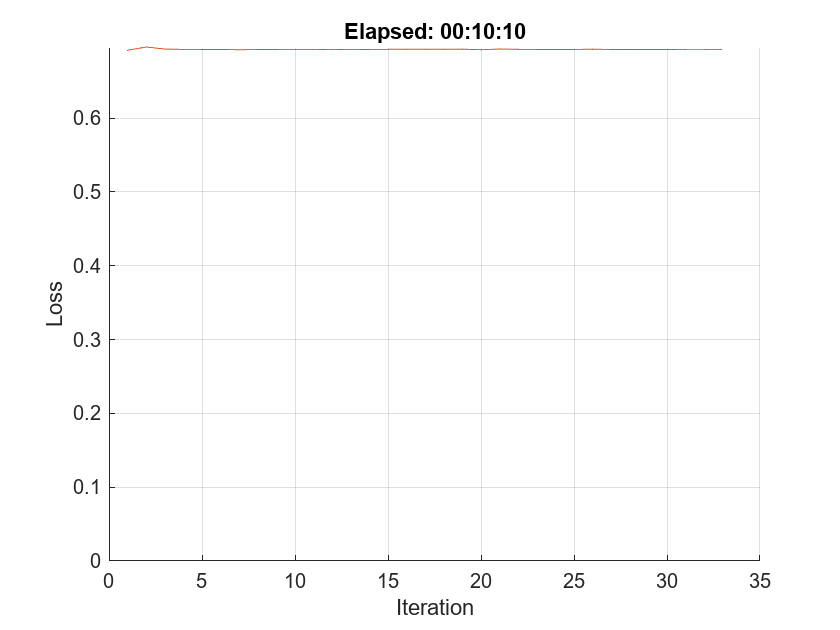

    34




% Generación iterativa del gráfico Función de pérdida vs. Iteración
for iteration = 1:numIterations
    disp(iteration)

    % Extracción de una muestra 
    [X1,X2,pairLabels] = getSiameseBatch(imds_train,miniBatchSize);
   

    % Conversión de los datos de la muestra a dlarray
    % (parámetro "SSCB" (spatial, spatial, channel, batch) for image data)

    X1 = dlarray(X1,"SSCUB");
    X2 = dlarray(X2,"SSCUB");

    % Conversión a gpuarray si se utiliza una GPU
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        disp('  - GPUARRAY')
        X1 = gpuArray(X1);
        X2 = gpuArray(X2);
    end

    % Uso de la función auxiliar dlfeval para calcular la pérdida del modelo y los gradientes
    [loss,gradientsSubnet,gradientsParams] = dlfeval(@modelLoss,net,fcParams,X1,X2,pairLabels);

    % Actualización de los parámetros de la CNN siamesa
    [net,trailingAvgSubnet,trailingAvgSqSubnet] = adamupdate(net,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);

    % Actualización de los parámetros de la capa fully connected
    [fcParams,trailingAvgParams,trailingAvgSqParams] = adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);

    % Graficado de la función de pérdida
    D = duration(0,0,toc(start),Format="hh:mm:ss");
    lossValue = extractdata(loss);
    lossValue = double(lossValue)
    addpoints(lineLossTrain,iteration,lossValue);
    title("Elapsed: " + string(D))
    drawnow
end

% Intentos de usar GPU
% gpuDeviceCount()
% gpuDevice
% gpuDeviceTable

## 4) Test

% Inicialización de parámetros
accuracy = zeros(1,10);
accuracyBatchSize = 150;

imds_test = subset(imds_total, num_training+1:numel(files))
files_test = imds_test.Files;
parts_test = split(files_test,filesep);
labels_test = join(parts_test(:,(end-2):(end-1)),"-");
imds_test.Labels = categorical(labels_test);


for i = 1:10
    % Extracción de la muestra
    [X1,X2,pairLabelsAcc] = getSiameseBatch(imds_test,accuracyBatchSize);

    % Conversión de los datos de la muestra a dlarray
    % (parámetro "SSCB" (spatial, spatial, channel, batch) for image data)
    X1 = dlarray(X1,"SSCUB");
    X2 = dlarray(X2,"SSCUB");

    % Conversión a gpuarray si se utiliza una GPU
    if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
        X1 = gpuArray(X1);
        X2 = gpuArray(X2);
    end

    % Generación de predicción con la red CNN siamesa
    Y = predictSiamese(net,fcParams,X1,X2);

    % Conversión de las predicciones a valores binarios
    Y = gather(extractdata(Y));
    Y = round(Y);

    % Cálculo de la precisión media de cada muestra
    accuracy(i) = sum(Y == pairLabelsAcc)/accuracyBatchSize;
end

averageAccuracy = mean(accuracy)*100


%%%% PARA CUANDO SEPARE EL DATASET EN TRAIN Y TEST , HABRÍA QUE CARGAR LOS
%%%% DATOS TEST Y PONER ESTO AL PRINCIPIO DEL APARTADO 4 (TEST)
%url = "https://github.com/brendenlake/omniglot/raw/master/python/images_evaluation.zip";
%downloadFolder = tempdir;
%filename = fullfile(downloadFolder,"images_evaluation.zip");
%
%dataFolderTest = fullfile(downloadFolder,"images_evaluation");
%if ~exist(dataFolderTest,"dir")
%    disp("Downloading Omniglot test data (3.2 MB)...")
%    websave(filename,url);
%    unzip(filename,downloadFolder);
%end
%disp("Test data downloaded.")
%
%imdsTest = imageDatastore(dataFolderTest, ...
%    IncludeSubfolders=true, ...
%    LabelSource="none");
%
%files = imdsTest.Files;
%parts = split(files,filesep);
%labels = join(parts(:,(end-2):(end-1)),"_");
%imdsTest.Labels = categorical(labels);
%
%numClasses = numel(unique(imdsTest.Labels))